# Example Sphere

This example shows how to calculate the optical forces on a spherical particle using OTT.  This live script complements the `examples/example_sphere.m` script, both describe approximately the same functionality.

We begin by adding OTT to the Matlab path and configuring warnings.  This step may be optional if you already have OTT added to the path (for instance, if you installed OTT via the Matlab Add-ons menu).  The following asumes we are in the ott/examples/liveScripts directory, you may need to adjust this if you copy this script to some other location.

addpath('../../');

% Make warnings less obtrusive (optional)
ott.warning('once');
ott.change_warnings('off');

Next we define variables for the medium and sphere properties.

% Refractive index of particle and medium
n_medium = 1.33;
n_particle = 1.59;

% Wavelength of light in vacuum [m]
wavelength0 = 1064e-9;

% Calculate the wavelength in the medium
wavelength_medium = wavelength0/n_medium;

% Radius of particle
radius = wavelength_medium * 0.5;

% Specify the numerical aparture of the beam/microscope
% This should be smaller than the refractive index of the medium
NA = 1.02;

# Setup the T-matrix for the particle


tic

% Create a T-matrix for a sphere
T = ott.Tmatrix.simple('sphere', radius, 'wavelength0', wavelength0, ...
    'index_medium', n_medium, 'index_particle', n_particle);

disp(['T-matrix calculation took ' num2str(toc) ' seconds']);

T-matrix calculation took 0.0081749 seconds


# Calculate the beam shape coefficients

This example supports a couple of different kinds of beams.  The toolbox supports other kinds of beams, see documentation for more details.

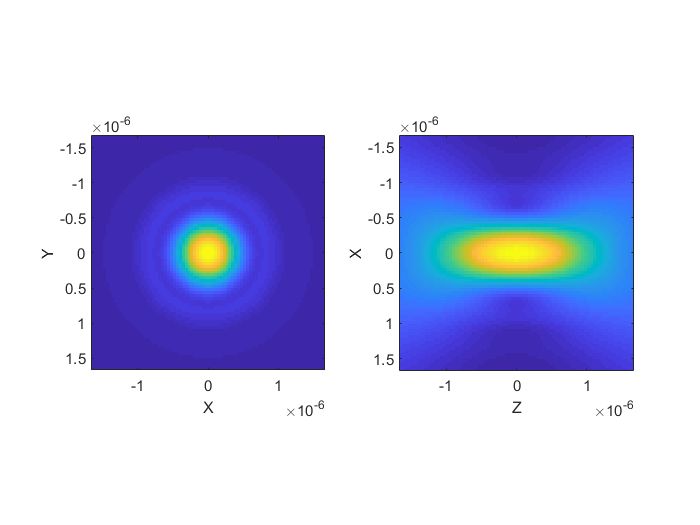


% Set the beam type (for this example we can choose lg, gaussian or hg)
% This is used bellow to select from the beam presets
beam_type = 'gaussian';

tic

switch beam_type
  case 'gaussian'

    % Create a simple Gaussian beam with circular polarisation
    % We could also calculate the beam angle ourseves and specify that.
    beam = ott.BscPmGauss('NA', NA, 'polarisation', [ 1 1i ], ...
        'index_medium', n_medium, 'wavelength0', wavelength0);

  case 'lg'

    % Create a LG03 beam with circular polarisation
    beam = ott.BscPmGauss('lg', [ 0 3 ], ...
        'polarisation', [ 1 1i ], 'NA', NA, ...
        'index_medium', n_medium, 'wavelength0', wavelength0);

  case 'hg'

    % Create a HG23 beam with circular polarisation
    beam = ott.BscPmGauss('hg', [ 2 3 ], ...
        'polarisation', [ 1 1i ], 'NA', NA, ...
        'index_medium', n_medium, 'wavelength0', wavelength0);

  otherwise
    error('Unsupported beam type');
end

% Normalize the beam power
beam.power = 1.0;

figure();
subplot(1, 2, 1);
beam.visualise();
subplot(1, 2, 2);
beam.visualise('axis', 'y');


disp(['Beam calculation took ' num2str(toc) ' seconds']);

Beam calculation took 1.6656 seconds


# Calculate axial force

To calculate the optical force on a particle we can use the `ott.forcetorque` function.  We generate a plot of the force for different axial displacements.


tic

% Calculate the force along z
z = [0;0;1]*linspace(-8,8,80)*wavelength_medium;
fz = ott.forcetorque(beam, T, 'position', z);

disp(['Force calculation took ' num2str(toc) ' seconds']);

Force calculation took 0.51471 seconds


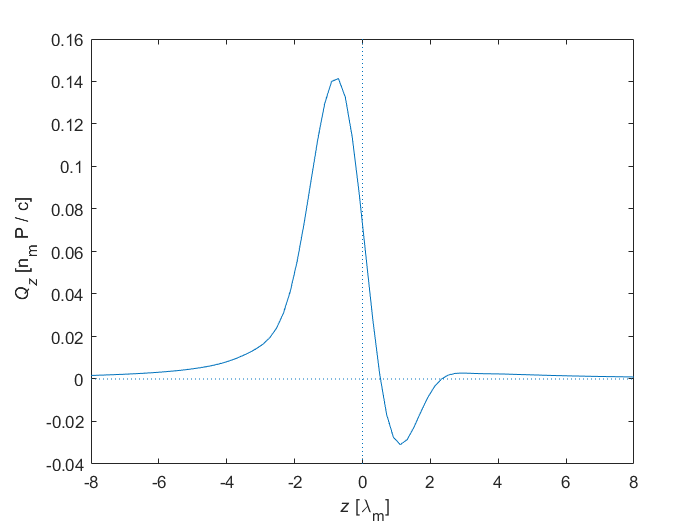


% Generate a plot
figure();
plot(z(3, :)/wavelength_medium,fz(3, :));
xlabel('{\it z} [\lambda_m]');
ylabel('{\it Q_z} [n_m P / c]');
aa = axis;
hold on;
line(aa(1:2),[ 0 0 ],'linestyle',':');
line([0 0],aa(3:4),'linestyle',':');
hold off;

# Calculate radial force

Next we generate a radial force plot.  First we start by finding the axial trap equilibrium and then we displace the particle radially outward from the equilibrium.

tic

% Find the equilibrium along the z axis
zeq = ott.find_equilibrium(z(3, :), fz(3, :));
if isempty(zeq)
  warning('No axial equilibrium in range!')
  zeq=0;
end
zeq = zeq(1);

% Calculate force along x-axis (with z = zeq, if found)
r = [1;0;0]*linspace(-4,4,80)*wavelength_medium + [0;0;zeq];
fr = ott.forcetorque(beam, T, 'position', r);

disp(['Force calculation took ' num2str(toc) ' seconds']);

Force calculation took 0.79681 seconds


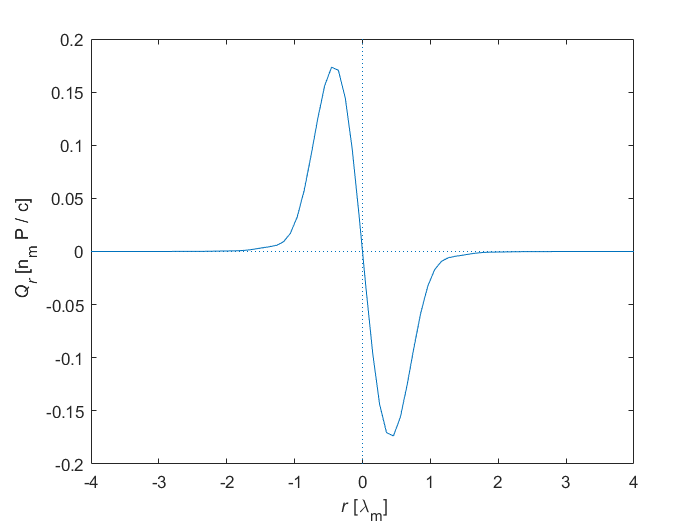


% Generate a plot
figure();
plot(r(1, :)/wavelength_medium,fr(1, :));
xlabel('{\it r} [\lambda_m]');
ylabel('{\it Q_r} [n_m P / c]');
aa = axis;
hold on;
line(aa(1:2),[ 0 0 ],'linestyle',':');
line([0 0],aa(3:4),'linestyle',':');
hold off;

## About

This example live script is part of OTT.  Written by Isaac Lenton.  For further details see [https://github.com/ilent2/ott](https://github.com/ilent2/ott)